# MC2: Tracking the embodied dynamics of cognition using computer mouse tracking

Stefan Scherbaum & Martin Schoemann

## Overview

In this MATLAB Live Script, we will have a hands-on look at the embodied dynamics of your own cognition during the [Henik task](https://doi.org/10.3758/BF03202431) which had been implemented and ran in [OpenSesame](https://osdoc.cogsci.nl/3.3/) using the [mousetrap plugin](https://github.com/PascalKieslich/mousetrap-os).

Since we have two separate analysis pipelines both in [R](https://www.r-project.org/) and [Matlab](https://www.mathworks.com/products/matlab.html), we will go through both shared and unique analysis steps. As a rough overview, we will cover:

- Data import

- Geometric processing

- Re-sampling and interpolation

- Visualization

- Summary measures

- Continuous measure

- Statistical analysis

%% general script settings
clear all; clc;
cd(fileparts(matlab.desktop.editor.getActiveFilename))

## Data import

Our pipeline here in Matlab starts with importing the raw data, combine the single data from each participant, and turning them into a structure that we can easily work with, that is, some of our convenient functions are optimized for.  

datapath = '../dataRaw/';
files = dir([datapath 'subject-*.csv']);
pdata = repmat(struct,1,numel(files));

stimlock_samples=5*1000; %assuming 5s of sampling every 1ms

for p=1:numel(files)
    fname =fullfile(files(p).folder,files(p).name);
    tmp = readtable(fname);
    
    %trial data
    pdata(p).p_num = p;
    pdata(p).t_condition = tmp.Condition';
    pdata(p).t_bignumber = tmp.NumberBig';
    pdata(p).t_smallnumber = tmp.NumberSmall';
    pdata(p).t_bignumberposition = tmp.NumberPositionBig';
    pdata(p).c_correct = tmp.correct';
    pdata(p).c_direction = [];

    %mt data (filled with NaNs)
    pdata(p).t_stimlock = cellfun(@(x) str2double(splitStr(x(2:end-1),', ')), tmp.timestamps_mousetrap_afterhover, 'UniformOutput', false);
    pdata(p).t_stimlock = cell2mat(cellfun(@(x) normLength(x,stimlock_samples,0), pdata(p).t_stimlock, 'UniformOutput', false));
    pdata(p).x_stimlock = cellfun(@(x) str2double(splitStr(x(2:end-1),', ')), tmp.xpos_mousetrap_afterhover, 'UniformOutput', false);
    pdata(p).c_direction = cell2mat(cellfun(@(x) sign(x(end)), pdata(p).x_stimlock, 'UniformOutput', false))';
    pdata(p).x_stimlock = cell2mat(cellfun(@(x) normLength(x,stimlock_samples,0), pdata(p).x_stimlock, 'UniformOutput', false));
    pdata(p).y_stimlock = cellfun(@(x) str2double(splitStr(x(2:end-1),', ')), tmp.ypos_mousetrap_afterhover, 'UniformOutput', false);
    pdata(p).y_stimlock = cell2mat(cellfun(@(x) normLength(x,stimlock_samples,0), pdata(p).y_stimlock, 'UniformOutput', false));
end%for

## Geometric Processing

So, the data are imported and available `pdata` in a convenient structure. Now, we look at the cursor trajectories from only one participant in order to learn about:

- how OpenSesame has tracked the cursor position

- what geometric processing steps we need to apply

- to get a feeling for the cursor trajectories

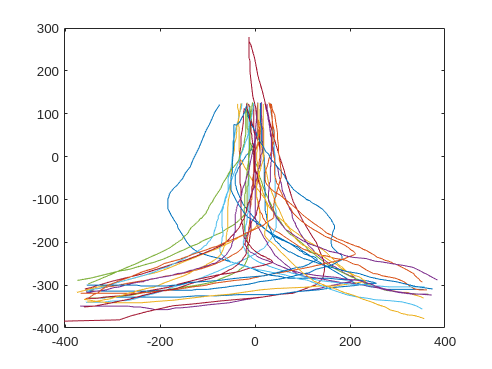

p=1;
plot(pdata(p).x_stimlock',pdata(p).y_stimlock')

The plot shows the raw cursor trajectories from the first participant in the struct array, and we can see that the trajectories were tracked in a somewhat twisted way, that is, the coordinate system in OpenSesame was centered in middle of the screen and going upwards toward the response boxes decreased the y-coordinate. We can also see that the trajectories differ in their starting point (i.e., the cursor position in the moment the stimuli were presented) and end point (i.e., the first cursor position in one of the response boxes). And, we see that trajectories going into different response boxes cannot easily be compared as they end in opposite directions. Therefore, we remap the trajectories and align their starting point.

for p=1:numel(pdata)
    % mirror on the horizontal axis
    pdata(p).y_stimlock = pdata(p).y_stimlock*(-1);
    %mirror on the vertical axis, to the left
    pdata(p).x_stimlock = bsxfun(@times, pdata(p).x_stimlock, pdata(p).c_direction'*(-1));
    %align x coordinates to zero as starting point
    pdata(p).x_stimlock = bsxfun(@minus,pdata(p).x_stimlock, pdata(p).x_stimlock(:,1));
    %set timestamps to zero at starting point
    pdata(p).t_stimlock = bsxfun(@minus,pdata(p).t_stimlock, pdata(p).t_stimlock(:,1));
end%for

## Re-sampling and interpolation

So, the trajectories are in principle comparable but before we can do that in meaningful way, we have to focus on a significant characteristic of such trajectories (well, frankly, that applies to all kinds of time-continuous data), namely, that they are of different lengths. We cannot easily see that characteristic when we plot the trajectories on the x/y-plane, but when we plot both `x_stimlock` and `y_stimlock` as a function of `t_stimlock`.

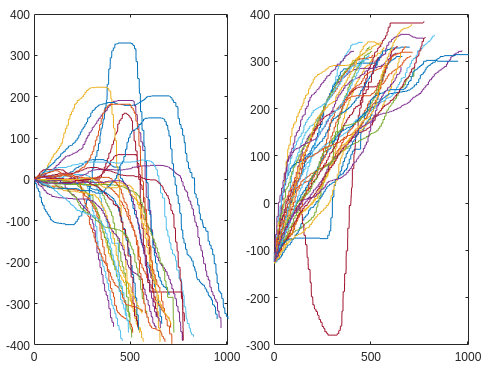

p=1;
tiledlayout(1,2,'TileSpacing','compact','Padding','compact');
nexttile
plot(pdata(p).t_stimlock',pdata(p).x_stimlock')
nexttile
plot(pdata(p).t_stimlock',pdata(p).y_stimlock')

Different lengths can be due to different sampling frequencies, different times participants took to reach a response box (i.e., because they took short/longer paths or moved the cursor faster/slower), or both. Both aspects can be treated by re-sampling and interpolation in such a way that each trajectory is represented by an equal number of points. Time-normalization interpolates trajectories such that they are represented by exactly the same number of temporally equidistant data points, and the number is typically chosen to be 101 (`calcTrajectories()`). Length-normalization interpolates the trajectory into the same number of spatially equidistant data points (not implemented). Another way of representing each trajectory by an equal number of data points is to interpolate the trajectories such that timestamps are equidistant from each other and to fill up each trajectory with its own last data point times the number of data points that are needed to obtain the same length as the longest trajectory in the data (`normLength()`); thus the longest trajectory in the data determines the length of all other trajectories and is hence not filled up.

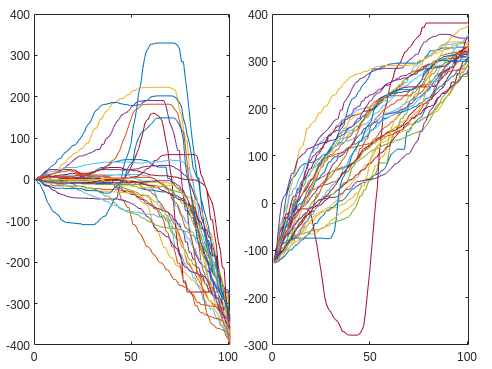

for p=1:numel(pdata)
    [pdata(p).x_warp,pdata(p).y_warp]=calcTrajectories(pdata(p).x_stimlock,pdata(p).y_stimlock,101);
end%for

p=1;
tiledlayout(1,2,'TileSpacing','compact','Padding','compact');
nexttile
plot([1:101],pdata(p).x_warp')
nexttile
plot([1:101],pdata(p).y_warp')